## Forward kinematics on armpi_fpv

This example shows how to compute forward kinematics for the end effector of armpi_fpv. Specifically, it computes the position of the robot's gripper in terms of its $x, y, z$ coordinates. This example is constructed based on the tutorial here: [https://fr.mathworks.com/help/sm/ref/simscape.multibody.kinematicssolver.html](https://fr.mathworks.com/help/sm/ref/simscape.multibody.kinematicssolver.html)

### Create a `KinematicsSolver` object for the robot

We first load the multibody simulation model of the robot and create a KinematicsSolver object.

clear; clc;

%% Import the model.
mdl = 'armpi_fpv_step_3_inverse_forward_kinematics';
load_system(mdl);
% Create a KinematicsSolver object.
kine_solve = simscape.multibody.KinematicsSolver(mdl);

### Define frame variables

`Now, kine_solve is defined as a kinematics solver that can solve the forward and inverse kinematics problem numerically. Forward kinematics solves a problem that knowing the states of joints, how to calculate the state of the end effector. `

`To solve this problem using `the `KinematicsSolver object, we need to first define teh end effector and specify its coordination system is defined based on which frame. This relationship is encoded as frame variables in `the `KinematicsSolver object.`

`The following cell of code defines an end effector as "follower", and the reference cooridination system as "base". Both needs to be defined as a port in a frame of the multibody model. `

`Here, we use "addFrameVariables" function to tell `the `KinematicsSolver object how do we define the end effector and what are the metrics we want for the end effector: "translation" indicates the position related to the base, while "rotation" indicates the degree of rotation with respect to the base.`

base = [mdl '/robot_armpi_fpv' '/World/W'];
follower = [mdl '/robot_armpi_fpv' '/gripper_base/F'];
addFrameVariables(kine_solve, "gripper_base", "translation", base, follower);
addFrameVariables(kine_solve, "gripper_base", "rotation", base, follower);
frameVariables(kine_solve)

ans = 6×4 table
                 ID                                                 Base                                                                       Follower                                      Unit 
    ____________________________    _____________________________________________________________________    ____________________________________________________________________________    _____

    "gripper_base.Translation.x"    "armpi_fpv_step_3_inverse_forward_kinematics/robot_armpi_fpv/World/W"    "armpi_fpv_step_3_inverse_forward_kinematics/robot_armpi_fpv/gripper_base/F"    "m"  
    "gripper_base.Translation.y"    "armpi_fpv_step_3_inverse_forward_kinematics/robot_armpi_fpv/World/W"    "armpi_fpv_step_3_inverse_forward_kinematics/robot_armpi_fpv/gripper_base/F"    "m"  
    "gripper_base.Translation.z"    "armpi_fpv_step_3_inverse_forwa

### Define target variables

Target variables in the `KinematicsSolver object defines what we know about the robot. In a forward kinematics problem, target variables are often the positions of the motors.`

`To implement this, we need to get the IDs of motors:`

jointPositionVariables(kine_solve)

ans = 11×4 table
        ID           JointType                                        BlockPath                                    Unit 
    __________    ________________    _________________________________________________________________________    _____

    "j1.Rz.q"     "Revolute Joint"    "armpi_fpv_step_3_inverse_forward_kinematics/robot_armpi_fpv/joint1"         "deg"
    "j2.Rz.q"     "Revolute Joint"    "armpi_fpv_step_3_inverse_forward_kinematics/robot_armpi_fpv/joint2"         "deg"
    "j3.Rz.q"     "Revolute Joint"    "armpi_fpv_step_3_inverse_forward_kinematics/robot_armpi_fpv/joint3"         "deg"
    "j4.Rz.q"     "Revolute Joint"    "armpi_fpv_step_3_inverse_forward_kinematics/robot_armpi_fpv/joint4"         "deg"
    "j5.Rz.q"     "Revolute Joint"    "armpi_fpv_step_3_inverse_forward_kinematics/robot_armpi_fpv/joint5"         "deg"

Then, we can use "addTargetVariables" function to define the target variables using their IDs:

targetIDs = ["j1.Rz.q"; "j2.Rz.q"; "j3.Rz.q"; "j4.Rz.q"; "j5.Rz.q";];
addTargetVariables(kine_solve, targetIDs);

### Define the output of the FK analysis

Finally, we just need to tell `KinematicsSolver object what do we want it to calculate, i.e., the outputs. This is done by the "addOutputVariables" function. In this case, we would like to evaluate the `$x,y,z$ coordinates of the gripper base frame.

outputIDs = ["gripper_base.Translation.x"; "gripper_base.Translation.y"; "gripper_base.Translation.z"];
addOutputVariables(kine_solve, outputIDs);

### Calculate the positions of the end effector given inputs

First, let us try a simple case: if the five motors are in nominal positions with 0 degree of rotation, then, the robot should be in up-straight position.

targets = [0, 0, 0, 0, 0];
[outputVec, statusFlag] = solve(kine_solve,targets)

outputVec =     0.0000
   -0.0000
    0.3105


statusFlag = 1

% Visualize the result
viewSolution(kine_solve);

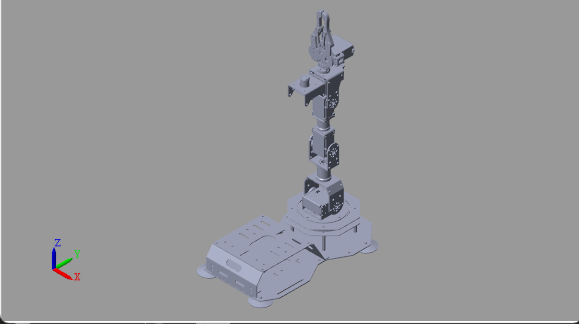

We can test a random combinations of the joints' states: [10, 10, 10, 10, 10]

targets = [10, 10, -30, 10, -10];
[outputVec, statusFlag] = solve(kine_solve, targets)

outputVec =    -0.0041
    0.0234
    0.3025


statusFlag = 1

% Visualize the result
viewSolution(kine_solve);

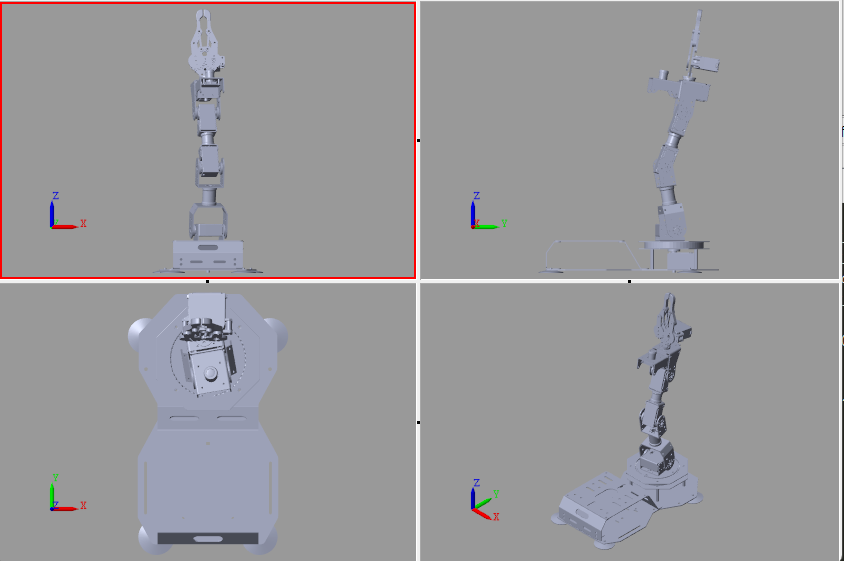

## Inverse kinematics

The analysis of inverse kinematics aims at calculating the positions of each motor, given the observed end effector positions. The process of applying inverse kinematics is the same as forward kinematics. We only need to switch the target and output variables.

clear; clc;

% Import the model.
mdl = 'armpi_fpv_step_1_direct_import';
load_system(mdl);
ik = simscape.multibody.KinematicsSolver(mdl);

% Define the base and follower frames.
base = 'armpi_fpv_step_1_direct_import/World/W';
follower = 'armpi_fpv_step_1_direct_import/gripper_base/F';
addFrameVariables(ik,"gripper_base", "translation", base, follower);
addFrameVariables(ik,"gripper_base", "rotation", base, follower);
frameVariables(ik)

ans = 6×4 table
                 ID                                   Base                                         Follower                        Unit 
    ____________________________    ________________________________________    _______________________________________________    _____

    "gripper_base.Translation.x"    "armpi_fpv_step_1_direct_import/World/W"    "armpi_fpv_step_1_direct_import/gripper_base/F"    "m"  
    "gripper_base.Translation.y"    "armpi_fpv_step_1_direct_import/World/W"    "armpi_fpv_step_1_direct_import/gripper_base/F"    "m"  
    "gripper_base.Translation.z"    "armpi_fpv_step_1_direct_import/World/W"    "armpi_fpv_step_1_direct_import/gripper_base/F"    "m"  
    "gripper_base.Rotation.x"       "armpi_fpv_step_1_direct_import/World/W"    "armpi_fpv_step_1_direct_import/gripper_base/F"    "deg"
    "gripper_base.Rotatio

% Define the target variables.
targetIDs = ["gripper_base.Translation.x"; "gripper_base.Translation.y"; "gripper_base.Translation.z"];
addTargetVariables(ik, targetIDs);

% Define outputs
outputIDs = ["j1.Rz.q"; "j2.Rz.q"; "j3.Rz.q"; "j4.Rz.q"; "j5.Rz.q"];
addOutputVariables(ik,outputIDs);

### Test the inverse kinematics - I

Let us first try targets = [0, 0, 0.3105], which corresponds to the up-straight position. So the theoretical solutions should be [0, 0, 0, 0, 0].

targets = [0, 0, 0.3105]

targets =          0         0    0.3105


[outputVec,statusFlag] = solve(ik,targets)

outputVec =     0.0028
    0.3716
   -0.2662
   -1.0387
    0.0051


statusFlag = 1

viewSolution(ik);

We can see we have some small errors but it is tolerable. Below is the visulization result:

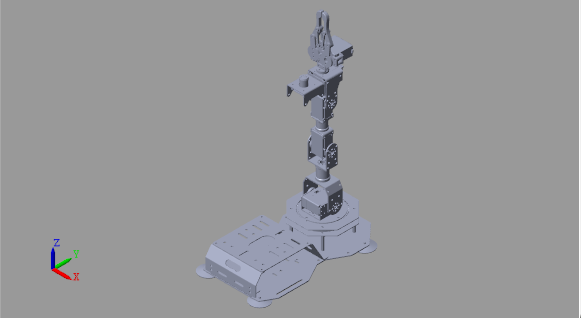

### Test the inverse kinematics - I

Let us first try targets = [-0.0041, 0.0234, 0.3025], which corresponds to the second test case of the forward kinematics. So the theoretical solutions should be [10, 10, -30, 10, -10].

targets = [-0.0041, 0.0234, 0.3025]

targets =    -0.0041    0.0234    0.3025


[outputVec,statusFlag] = solve(ik,targets)

outputVec =     9.9381
    9.5943
  -21.4248
  -12.7397
    0.0051


statusFlag = 1

viewSolution(ik);

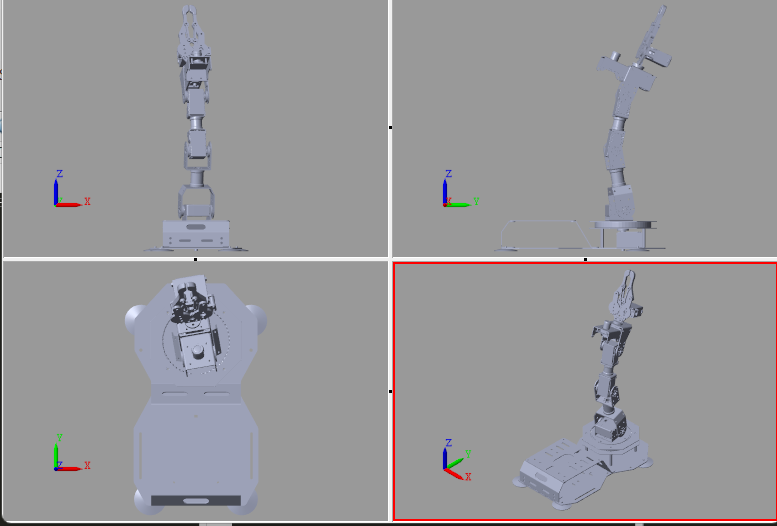

We can see some errors. This could be caused by the fact that the problem of inverse kinematics is indetermint: Multiple solutions might lead to the same result. To improve the performance, we could try to give an initial guess of some values.

guessesIDs = ["j3.Rz.q","j4.Rz.q"];
guesses = [-35, 8];
addInitialGuessVariables(ik, guessesIDs);
[outputVec,statusFlag] = solve(ik,targets,guesses)

outputVec =     9.9381
    9.9907
  -30.0076
   10.0599
    0.0051


statusFlag = 1

Now the solution is much better. Note that the element in the solution is related to the rotation of joint 5, which does not affect the position of the end effector in the 3-d space. That it why its estimation is not accurate.